simulation of an Arithmetic Brownian

motion and the value of the variable at the last step:

clear all
close all

mu = 0.1; % Drift coefficient
sigma = 0.2; % Diffusion coefficient (volatility)
X0 = 50; % Initial price
T = 1; % Time to maturity (1 year)
N = 252; % Number of time steps (daily steps for one year)
dt = T/N; % Time step

X(1) = X0;

dW = sqrt(dt) * randn(N, 1)

dW =     0.0181
    0.0110
    0.0714
   -0.0174
    0.0298
   -0.0351
    0.0579
   -0.1061
    0.0153
    0.0469



    for t = 1:N
        X(t+1) = X(t) + mu*dt + sigma * dW(t);
    end

X(end)

ans = 50.0278

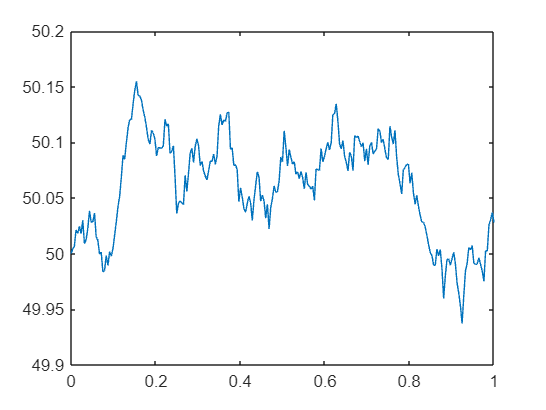


figure;
plot(0:dt:T, X);

Geometric Brownian motion.

clear all

mu = 0.1; % Drift coefficient
sigma = 0.2; % Diffusion coefficient (volatility)
S0 = 50; % Initial price
T = 1; % Time to maturity (1 year)
N = 252; % Number of time steps (daily steps for one year)
dt = T/N; % Time step

S(1) = S0;

dW = sqrt(dt) * randn(N, 1)

dW =     0.0213
    0.0893
   -0.0177
   -0.1253
    0.0192
   -0.0279
   -0.0593
   -0.0409
    0.0609
   -0.0946



    for t = 1:N
        S(t+1) = S(t) * exp((mu - 0.5 * sigma^2) * dt + sigma * dW(t));
    end

S(end)

ans = 60.8609

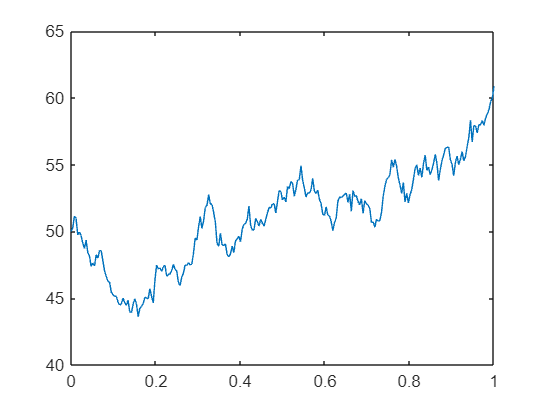

figure;
plot(0:dt:T, S);

Same as before, but with sample path : M = 1000

mean and standard deviation and comparion to theoretical values.

mu = 0.1; % Drift coefficient
sigma = 0.2; % Diffusion coefficient (volatility)
S0 = 50; % Initial price
T = 1; % Time to maturity (1 year)
N = 252; % Number of time steps (daily steps for one year)
M = 1000; % Number of paths
dt = T/N; % Time step

    for j = 1:M
        dW = sqrt(dt) * randn(N, 1);
        for t = 1:N
            S(1, j) = S0;
            S(t+1, j) = S(t, j) * exp((mu - 0.5 * sigma^2) * dt + sigma * dW(t));
        end
    end

meanS = mean(S, 2);
stdS = std(S, 0, 2);

exp_mean = meanS(end)

exp_mean = 54.8772

exp_std = stdS(end)

exp_std = 11.0281

theoretical_mean = S0 * exp(mu * T)

theoretical_mean = 55.2585

theoretical_std = S0 * exp(mu * T) .* sqrt(exp(sigma^2 * T) - 1)

theoretical_std = 11.1632

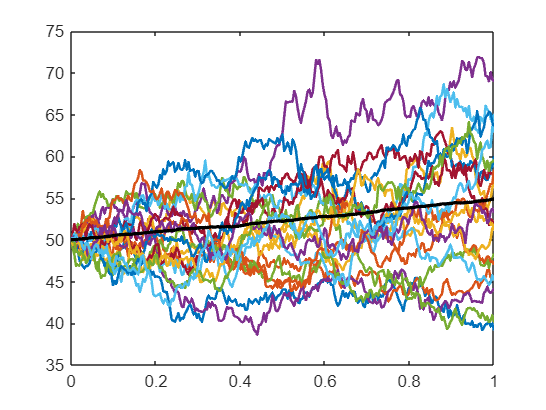

figure;

plot(0:dt:T, S(:, 1:20), 'LineWidth', 1.5); % Plot the first 10 paths forillustration
hold on;
plot(0:dt:T, meanS, 'k', 'LineWidth', 2); % Plot the mean path